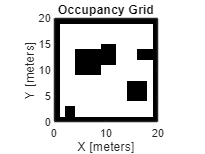

% Define the variable g with a value of 4, it will be the map selector
g = 4;

% Load the trained MPNet network from the specified file
network = load("2D\DL\mpnet.mat", "mpnet");

% Load the occupancy map data for the specified map number (g)
load("2D\occupancy_map_data" + g + ".mat")


% Load the occupancy map for the specified map number (g)
load("2D\occupancy_map" + g + ".mat")

% Create an occupancyMap object from the loaded occupancy map data (omap)
map = occupancyMap(omap);

% Define the starting position and orientation of the robot
start_x = 5;
start_y = 8;
start_orientation = 0;

% Define the goal position and orientation for the robot
goal_x = 17;
goal_y = 17;
goal_orientation = 0;

% Combine the start position and orientation into a single pose variable
robot_pose = [start_x, start_y, start_orientation];

% Combine the goal position and orientation into a single pose variable
goal_pose = [goal_x, goal_y, goal_orientation];

% Extract the mpnet network from the loaded network structure
mpnet = network.mpnet;
show(map)

% Create a state space for SE(2) (Special Euclidean group in 2D)
ss = stateSpaceSE2;

% Set the state bounds for the state space
% The bounds are defined as:
%   - x: [0, 200]
%   - y: [0, 200]
%   - theta (orientation): [-pi, pi]
ss.StateBounds = [[0 200]; [0 200]; [-3.1416 3.1416]];

% Create a state sampler using MPNet within the specified state space
stateSamplerDL = stateSamplerMPNET(ss, mpnet);

% Define the start and goal states using the robot's initial and goal poses
start = robot_pose;
goal = goal_pose;

% Set the environment map for the state sampler
stateSamplerDL.Environment = map;

% Set the start state for the state sampler
stateSamplerDL.StartState = start;

% Set the goal state for the state sampler
stateSamplerDL.GoalState = goal;

% Create a state validator using the occupancy map
% The validator checks if states are valid (i.e., not in collision)
stateValidator = validatorOccupancyMap(ss, Map=map);

% Set the validation distance for the state validator
% This is the distance between state samples when validating a path
stateValidator.ValidationDistance = 0.1;


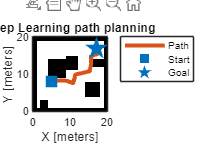

% Create an RRT* planner with the specified state space and state validator
% The planner uses deep learning sampling for state selection
% MaxConnectionDistance specifies the maximum distance between connected states
plannerDLSampling = plannerRRTStar(ss, stateValidator, MaxConnectionDistance=2, StateSampler=stateSamplerDL);

% Plan a path from the start state to the goal state using the RRT* planner
% The path and solution information are returned
[pathDLSampling, solutionInfoDLSampling] = plan(plannerDLSampling, start, goal);

% Create a new figure for displaying the results
figure

% Show the occupancy map in the figure
show(map);

% Hold the current figure to overlay additional plots
hold on;

% Plot the planned path on the map
% The path is plotted using the X and Y coordinates of the states in the path
plot(pathDLSampling.States(:,1), pathDLSampling.States(:,2), plannerLineSpec.path{:})

% Plot the start state on the map
plot(start(1), start(2), plannerLineSpec.start{:})

% Plot the goal state on the map
plot(goal(1), goal(2), plannerLineSpec.goal{:})

% Add a legend to the figure, located outside the northeast of the plot
legend(Location="northeastoutside")

% Add a title to the figure
title("Deep Learning path planning")